**Respuesta natural**

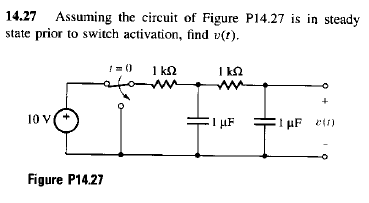

clc, clear, close all
format short g
syms s t

Primero analizamos el circuito antes de desconecatar la fuente, es decir en (0-) donde el capacitor se comporta como circuito abierto, vemos que en t=0- el circuito está abierto por lo que no circula corriente por lo tanto no hay caida de tension en los resistores y lña tension v(t) es igual a la de la fuente, es decir en **t<0  v(t) = 10V**. con eso ya tenemos las condiciones iniciales.

Procedemos a analizar el circuito despues de que se desconecta la fuente

vf = 10; %[V]

c = 1e-6; %[F]

z1 = 1e3;
z2 = 1/(s*c);
z3 = 1e3;
z4 = 1/(s*c);

primero hallamos la funcion de transferencia

pz1_z2 = 1/(1/z1 + 1/z2) + z3;

zs = simplify(1/( (1/z4) + 1/(pz1_z2) ))

$$zs = \frac{1000000\,\left(s+2000\right)}{s^{2}+3000\,s+1000000}$$

teniendo el denominador de la función de transferencia, extraemos sus polos

p = roots([1 3000 1e6]) %los exponentes de las exponenciales de respuesta natural

p =         -2618
      -381.97


de esta manera la respuesta natural tendria esta forma

syms A1 A2 e
rn = A1*e^(-382) + A2*e^(-2618)

$$rn = \frac{A_{1}}{e^{382}}+\frac{A_{2}}{e^{2618}}$$

Ahora porcedemos a clacular sus constentes que dependen de las condiciones iniciales

v0 = 10;